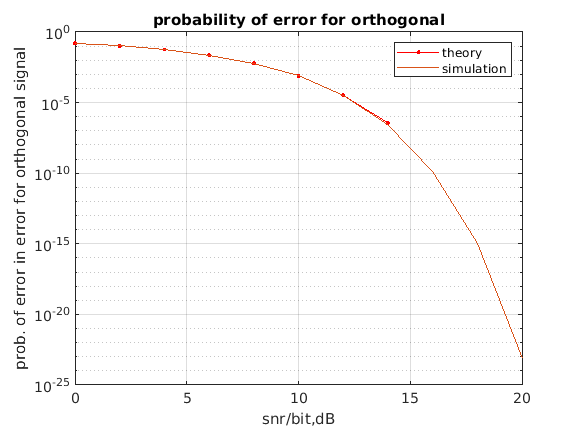

close all;
clear all;
clc;

snr_dB=[0 2 4 6 8 10 12 14 16 18 20];
snr=10.^(snr_dB/10);

for k=1:length(snr_dB)
    avg_error=0;
    error=0;
    I=10000;
    bits=20000;
    for l=1:I
        s=randsrc(1,bits,[1,-1i]);
        No=sqrt(10.^-(snr_dB/10)/2);
        n=No(k)*(randn(1,bits)+1i*randn(1,bits));
        O=s+n;
        for m=1:length(O)
            if ((real(O(m))+imag(O(m))>0 && s(m)==-1i)||(real(O(m))+imag(O(m))<0 && s(m)==1))
                error=error+1;
            end
        end
        error=error/bits;
        avg_error=avg_error+error;
        
    end
    
    BER(k)=avg_error/I;
end

semilogy(snr_dB,BER,'.-r');
prob.error=0.5.*erfc(sqrt(snr/2));
hold on 
semilogy(snr_dB,prob.error,'-');
grid on
legend('theory','simulation');
xlabel('snr/bit,dB');
ylabel('prob. of error in error for orthogonal signal');
title('probability of error for orthogonal');